# 4.3 按频率抽取的 FFT 与 IFFT：DIF 蝶形、与 DIT 互为转置、用 FFT 程序算 IFFT

在 MATLAB 编辑器中打开，点击“运行”；或逐节运行。仅使用基础 MATLAB。

clearvars;
LIVE = strcmp(getenv('DSP_LIVE'), '1');
if LIVE, newpanel = @(varargin) figure('Color','w','Position',[80 80 640 420]); else, newpanel = @(varargin) nexttile(varargin{:}); end
if LIVE, set(groot, 'defaultLegendLocation', 'southoutside'); else, set(groot, 'defaultLegendLocation', 'best'); end
outdir = fullfile(fileparts(mfilename('fullpath')), 'results');
if ~exist(outdir, 'dir'), mkdir(outdir); end

## 演示1：两种蝶形的区别——DIT 先乘 W 再加减，DIF 先加减再乘 W（教材图 4.2.1 与 4.3.1）

a = 1 + 0.5i; b = 0.3 - 0.8i; W = exp(-2i*pi*1/8);
dit = [a + W*b, a - W*b];                          % 按时间抽取
dif = [a + b, (a - b)*W];                          % 按频率抽取

## 演示2：自己写按频率抽取的 FFT：自然顺序输入，v 级蝶形，输出位反转后再整理

N8 = 8; x8 = (1:8);
[X8, stages8] = fft_dif(x8);
xTest = randn(1, 1024) + 1i*randn(1, 1024);
errDIF = max(abs(fft_dif(xTest) - fft(xTest)));

## 演示3：IFFT 不必另写程序——x(n) = (1/N)·{DFT[X*(k)]}*（教材式 (4.3.8)）

n = 0:63; xr = cos(2*pi*5*n/64) + 0.5*sin(2*pi*13*n/64) + 0.1*(n == 10);
X = fft(xr);
xBack = conj(fft(conj(X)))/64;                     % 共轭 → FFT → 共轭 → 除 N
errIFFT = max(abs(xBack - xr));
errBuiltin = max(abs(ifft(X) - xr));

## 演示4：往返一次的误差量级：FFT 后 IFFT，任意长度

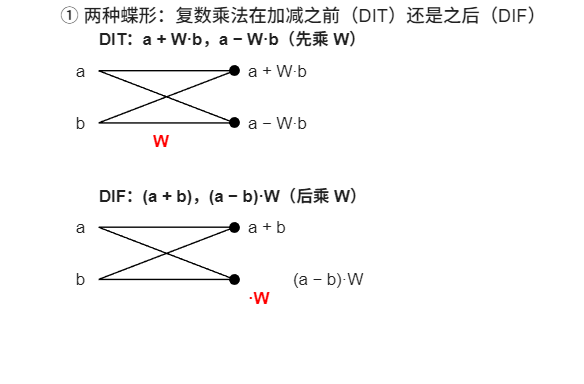

Nr = 2.^(4:12); rt = zeros(size(Nr));
for i = 1:numel(Nr), xx = randn(1, Nr(i)); rt(i) = max(abs(conj(fft(conj(fft(xx))))/Nr(i) - xx)); end

if ~LIVE, f1 = figure('Name','02 DIF 与 IFFT','Color','w','Position',[60 40 1250 900]); end
if ~LIVE, tiledlayout(2,2,'TileSpacing','compact','Padding','compact'); end
newpanel(); axis off; hold on; xlim([0 10]); ylim([0 6]);
% 画两只蝶形示意
draw_butterfly(0.5, 4.2, 'DIT：a + W·b，a − W·b（先乘 W）', true);
draw_butterfly(0.5, 1.2, 'DIF：(a + b)，(a − b)·W（后乘 W）', false);
title('① 两种蝶形：复数乘法在加减之前（DIT）还是之后（DIF）');

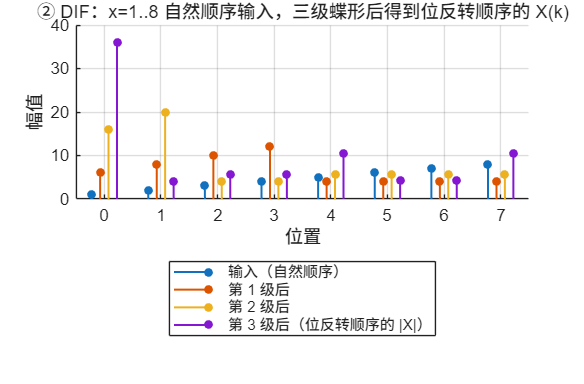

newpanel(); hold on;
for s = 1:size(stages8, 1)
    stem((0:7) + (s-2.5)*0.15, abs(stages8(s, :)), 'filled', 'MarkerSize', 4, 'LineWidth', 1.2);
end
grid on; xlim([-0.5 7.5]);
title('② DIF：x=1..8 自然顺序输入，三级蝶形后得到位反转顺序的 X(k)'); xlabel('位置'); ylabel('幅值');
legend('输入（自然顺序）','第 1 级后','第 2 级后','第 3 级后（位反转顺序的 |X|）');

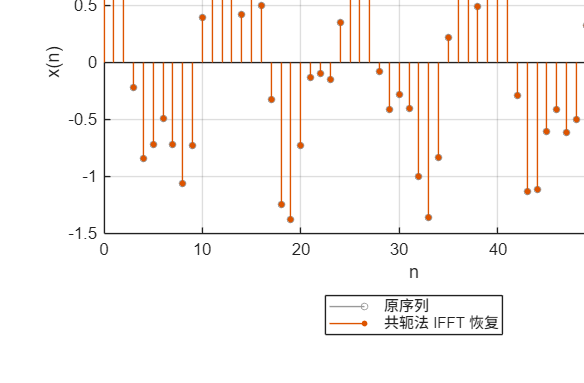

newpanel(); stem(n, xr, 'MarkerSize', 4, 'Color', [0.6 0.6 0.6]); hold on; stem(n, real(xBack), 'filled', 'MarkerSize', 3);
grid on; xlim([0 63]);
title(sprintf('③ IFFT = (1/N)·{FFT[X*]}*：与原序列最大差 %.1e', errIFFT)); xlabel('n'); ylabel('x(n)');
legend('原序列','共轭法 IFFT 恢复');

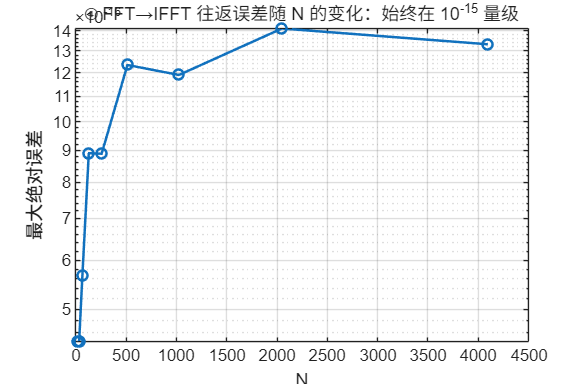

newpanel(); semilogy(Nr, rt, '-o', 'LineWidth', 1.5); grid on;
title('④ FFT→IFFT 往返误差随 N 的变化：始终在 10^{-15} 量级'); xlabel('N'); ylabel('最大绝对误差');

if ~LIVE, sgtitle('按频率抽取：与按时间抽取互为转置，运算量相同；IFFT 共用 FFT 程序'); end
if ~LIVE, prepare_export(f1); end
if ~LIVE, exportgraphics(f1, fullfile(outdir, '02-dif-ifft.png'), 'Resolution', 150); end

## 教师核验

assert(errDIF < 1e-9, '自写 DIF 与 fft 不一致');
assert(max(abs(X8 - fft(x8))) < 1e-12, 'N=8 DIF 结果不符');
assert(errIFFT < 1e-12 && errBuiltin < 1e-12, '共轭法 IFFT 不符');
assert(all(rt < 1e-12), '往返误差过大');
assert(abs(dit(1) - (a + W*b)) < 1e-15 && abs(dif(2) - (a - b)*W) < 1e-15, '蝶形算式不符');
metrics = struct('matlab_version', version, 'run_at', char(datetime('now','Format','yyyy-MM-dd HH:mm:ss')), ...
    'dif_vs_fft_max_err_1024', errDIF, 'X8_abs', abs(X8), 'ifft_conj_trick_err', errIFFT, 'ifft_builtin_err', errBuiltin, ...
    'roundtrip_N', Nr, 'roundtrip_err', rt, 'all_checks_passed', true);
fid = fopen(fullfile(outdir, 'verification-dif-ifft.json'), 'w', 'n', 'UTF-8'); assert(fid >= 0);
fprintf(fid, '%s\n', jsonencode(metrics, PrettyPrint=true)); fclose(fid);
disp(metrics); fprintf('\n课堂图已保存到：%s\n', outdir);

             matlab_version: '25.2.0.3360999 (R2025b) Update 7'
                     run_at: '2026-09-18 19:55:57'
    dif_vs_fft_max_err_1024: 6.1560e-14
                     X8_abs: [36 10.4525 5.6569 4.3296 4 4.3296 5.6569 10.4525]
        ifft_conj_trick_err: 4.5097e-16
           ifft_builtin_err: 4.4409e-16
                roundtrip_N: [16 32 64 128 256 512 1024 2048 4096]
              roundtrip_err: [4.4409e-16 4.4409e-16 5.6610e-16 8.9088e-16 8.8915e-16 1.2341e-15 1.1896e-15 1.4122e-15 1.3323e-15]
          all_checks_passed: 1


课堂图已保存到：C:\Users\Administrator\AppData\Local\Temp\Editor_lhbfa\results



function [X, stages] = fft_dif(x)
% 按频率抽取的基-2 FFT（教材 4.3）：自然顺序输入，v 级蝶形（先加减后乘 W），输出位反转。
x = x(:).'; N = numel(x); v = log2(N); assert(v == round(v), 'N 必须是 2 的幂');
X = x; stages = zeros(v + 1, N); stages(1, :) = X;
for s = v:-1:1                                     % 跨度从 N 逐级减半
    L = 2^s; half = L/2; W = exp(-2i*pi*(0:half-1)/L);
    for start = 1:L:N
        for k = 0:half-1
            a = X(start + k); b = X(start + k + half);
            X(start + k) = a + b; X(start + k + half) = (a - b) * W(k+1);   % DIF：后乘旋转因子
        end
    end
    stages(v - s + 2, :) = X;
end
order = zeros(1, N);                               % 输出是位反转顺序，整理回自然顺序
for m = 0:N-1, r = 0; q = m; for b = 1:v, r = r*2 + mod(q, 2); q = floor(q/2); end; order(m+1) = r + 1; end
X(order) = X;
end

function draw_butterfly(x0, y0, label, multBefore)
plot([x0 x0+3], [y0+1 y0+1], 'k'); plot([x0 x0+3], [y0 y0], 'k');
plot([x0 x0+3], [y0+1 y0], 'k'); plot([x0 x0+3], [y0 y0+1], 'k');
plot(x0+3, y0+1, 'ko', 'MarkerFaceColor', 'k'); plot(x0+3, y0, 'ko', 'MarkerFaceColor', 'k');
text(x0-0.3, y0+1, 'a', 'HorizontalAlignment', 'right'); text(x0-0.3, y0, 'b', 'HorizontalAlignment', 'right');
if multBefore
    text(x0+1.2, y0-0.35, 'W', 'Color', 'r', 'FontWeight', 'bold');
    text(x0+3.3, y0+1, 'a + W·b'); text(x0+3.3, y0, 'a − W·b');
else
    text(x0+3.3, y0-0.35, '·W', 'Color', 'r', 'FontWeight', 'bold');
    text(x0+3.3, y0+1, 'a + b'); text(x0+4.3, y0, '(a − b)·W');
end
text(x0, y0+1.6, label, 'FontWeight', 'bold');
end

function prepare_export(fig)
axesList = findall(fig, 'Type', 'axes');
for a = 1:numel(axesList), axesList(a).Toolbar.Visible = 'off'; end
drawnow;
end